## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 02 - Structural Representation and Code Organization**

#### **2.1 Structural Representation**

The first topic we hope to briefly discuss is how to represent an active structure in a virtural coding environment. This abstraction process is very important but is usually not discussed with sufficient detail. If you work in a specific field, there tends to be a "conventional model" that is widely accepted in that fields to the point where people stop discussing how the field discover and create that "conventional model" at the first place. However, here we do hope to spend some more time to talk about this topic as we will cover quite a lot of different active structures.

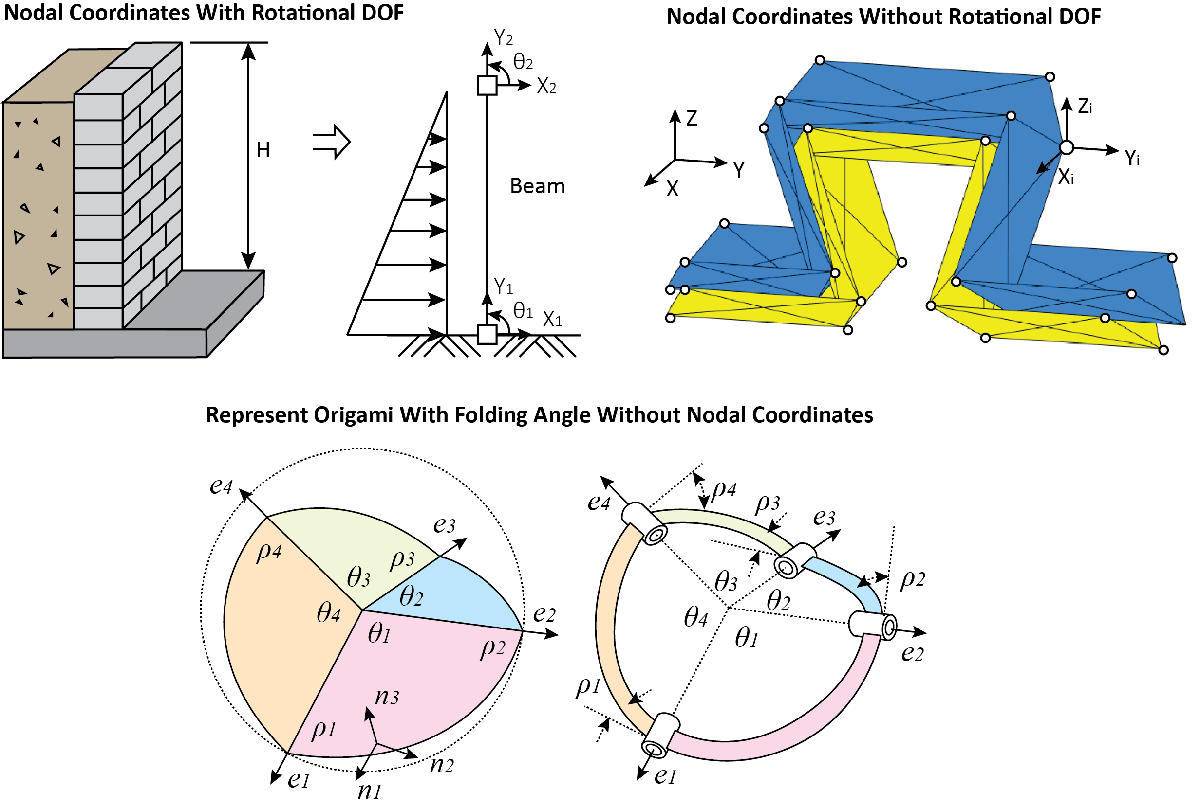

Typically in the simulation world, a mechanics or kienmatics model will represent an object using the nodal coordinates (with or without rotational degrees of freedom). The nodes used to represent the physical object are selected to best represent the system geometry (see figure above). However, please keep in mind that this is not always the case. For example, it is possible to simulate deployment kinematics of origami with rigid panels using the fold angles rather than nodal coordinates. If you are curious about how this works, you can check out T. Tachi's pioneering work in origami simulation:

[https://www.researchgate.net/profile/Tomohiro-Tachi/publication/228751289_Simulation_of_Rigid_Origami/links/569f2d2508ae4af52544b40c/Simulation-of-Rigid-Origami.pdf](https://www.researchgate.net/profile/Tomohiro-Tachi/publication/228751289_Simulation_of_Rigid_Origami/links/569f2d2508ae4af52544b40c/Simulation-of-Rigid-Origami.pdf)

Going back to our discussion with nodal coordinates, we can also choose to represents the node with or without rotational degrees of freedoms (DOFs). For node with rotational DOFs, they considers the translational motion and the rotational motion about the global cooridnate. In 2D this is $\left(x,y,\theta \;\right)$. in 3D this is $\left(x,y,z,\theta_{x\;} ,\theta_y ,\theta_z \right)$. One the other hand, for node without rotational DOFs, only the translation is needed to represent the geomety. In 2D this is $\left(x,y\;\right)$. in 3D this is $\left(x,y,z\right)$. The top left basement wall figure shows how we can use a beam model to reprent the masonry walls used to stop the soil. Here, we can use two nodes with rotational degrees of freedom to capture the wall and connect the two walls with a beam elements. On the top right figure, we have an origami system that is represented using nodal coordinates without rotational degrees of freedoms. In this model, the folding along origami creases is represented using a 4-node rotational spring element - which we will cover later. 

In this living textbook, my primary focus will be on developing models using nodes without rotational spring elements. 

#### **2.2 Introduction to Object-Oriented-Programming**

Here, we want to discuss a programming concept called object oriented programming (OOP). This is a necessary tool we need to use to organize the software program to avoid repeating code and also to create better architecture for the code. This allows other people to reuse the code we created, and also allows ourselves to reuse our code easily without the need to wondering "what I was doing when I wrote this a year ago" ;). The following figure introduces the concept of object oriented programming. There are two key concepts: Class and Object. 

Class is a virtualized object. It is not living in the RAM of our computer and thus cannot use CPU or GPU resources to do anything. We can think of it as the Peashooter Card in PVZ games. You know, it is a card that is not yet built on the grass boxes so it cannot shoot zombies. 

On the contrary, Object is a physicalized class. It is built based on the class. It is created to occupy RAM of our computer and thus it can use CPU and GPU resource to really compute results for us. With the PVZ example, object is like a Peashooter we actually plant on the grass box after paying the sunlight. This Peashooter object can now shoot the zombies! 

Multiple objects can be created from the same class. For instance we can create the ps1 Peashooter and the ps2 Peashooter based on the same Peashooter class. These objects can store variables to represent their own characteristics. For example, the ps1 Peashooter is at [1,1] location while the ps2 Peashooter is at [2,1] location. Finally, the objects can perform certain actions through using predefined functions. For example, we can ask the ps1 Peashooter to shoot down a zombie like "ps1.Shoot();"

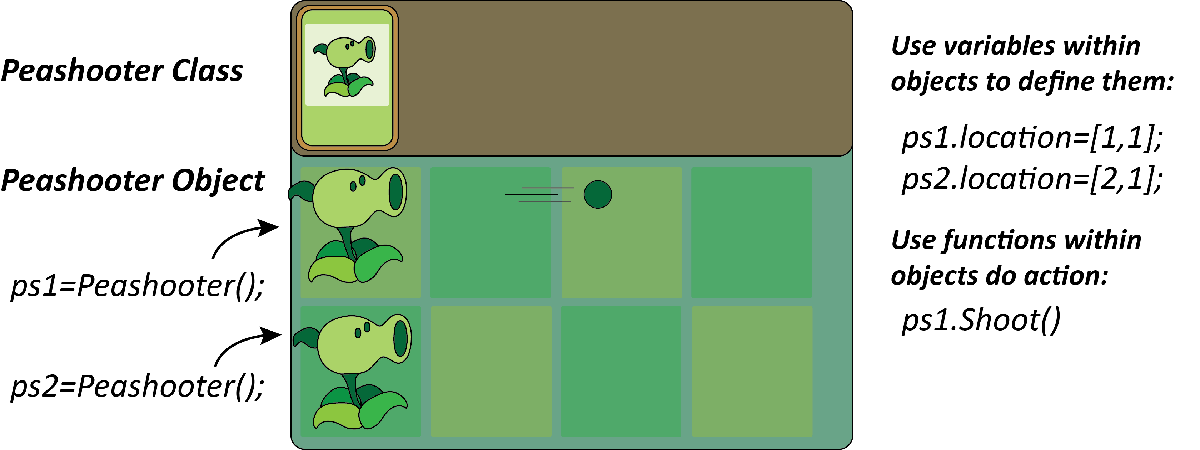

Now, why do we create the class? Because it help us to better organize the code as we start adding in mutliple truss elements or even when we add other elements. The class will help us avoid copy pasting codes and help us to navigate the code. Check out the source code of this package. Without using object oriented programming, we will have hundreds of functions stored in one folder! That is not ideal. More importantly, it allows other to change our code more easily without the need to actually go down deep into the source code. 

#### **2.3 Geting Started! Create an  Assembly to Represent an Active Structure**

Here, we hope to demonstrate how to use this package to simulate a simple active structure. In that process, we will try to understand how to use the OOP to organize the code and represent an active structure. Let's look at an active structure that can curl using the contracting and expanding active truss elements in the following figure. 

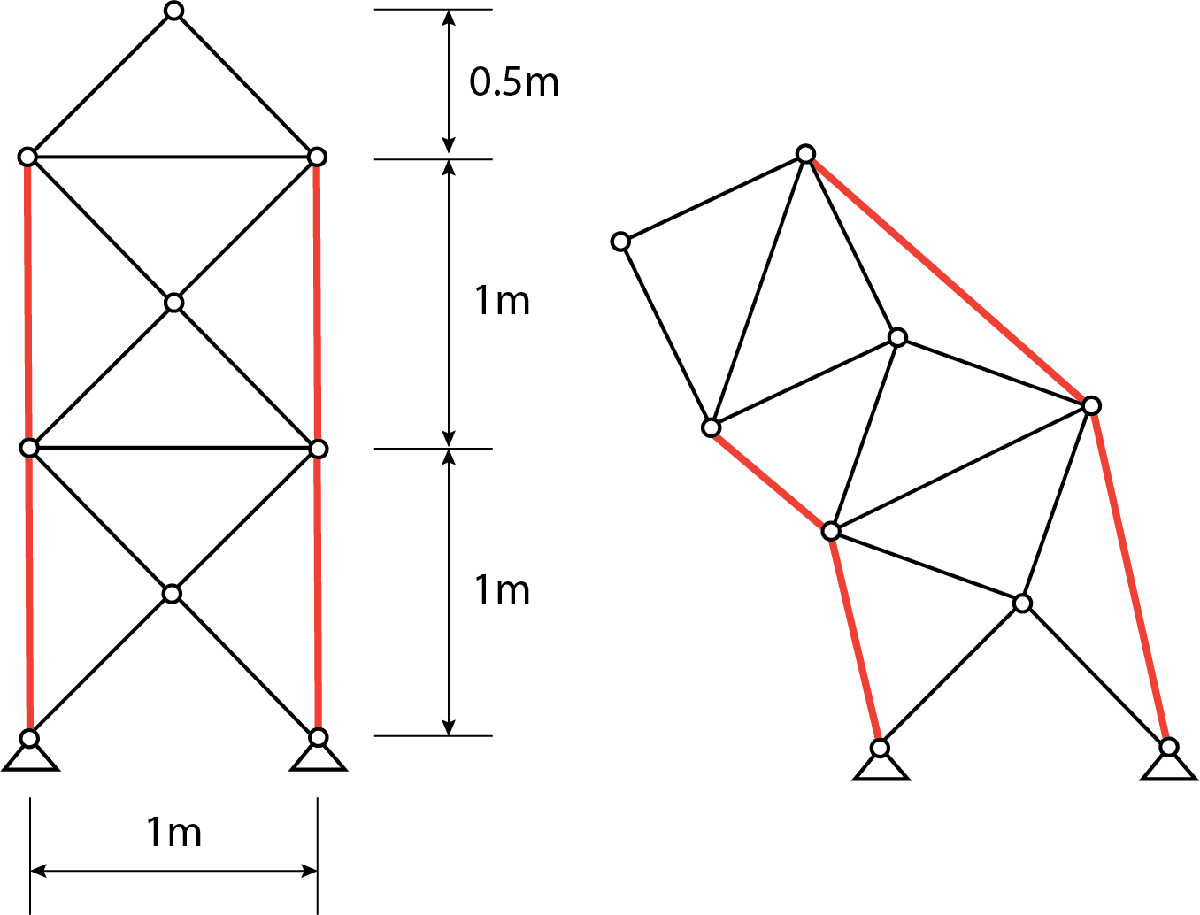

This model contains a couple items. First, we have the node (those circles). In the un-deformed configuration, each node has its own nodal coordinations. Next, we have those black lines representing conventional bars. These are bars made with common non-active materials (like steel or wood) and typically cannot generate large active deformation. Finally, we have the red thicker lines representing active bars (active truss). These bars are made with active materials that can produce large contraction or expansion when applying  stimuli. For example, if we apply stimuli to the left two bars and make them contract, the active truss will curl as shown in the right figure. 

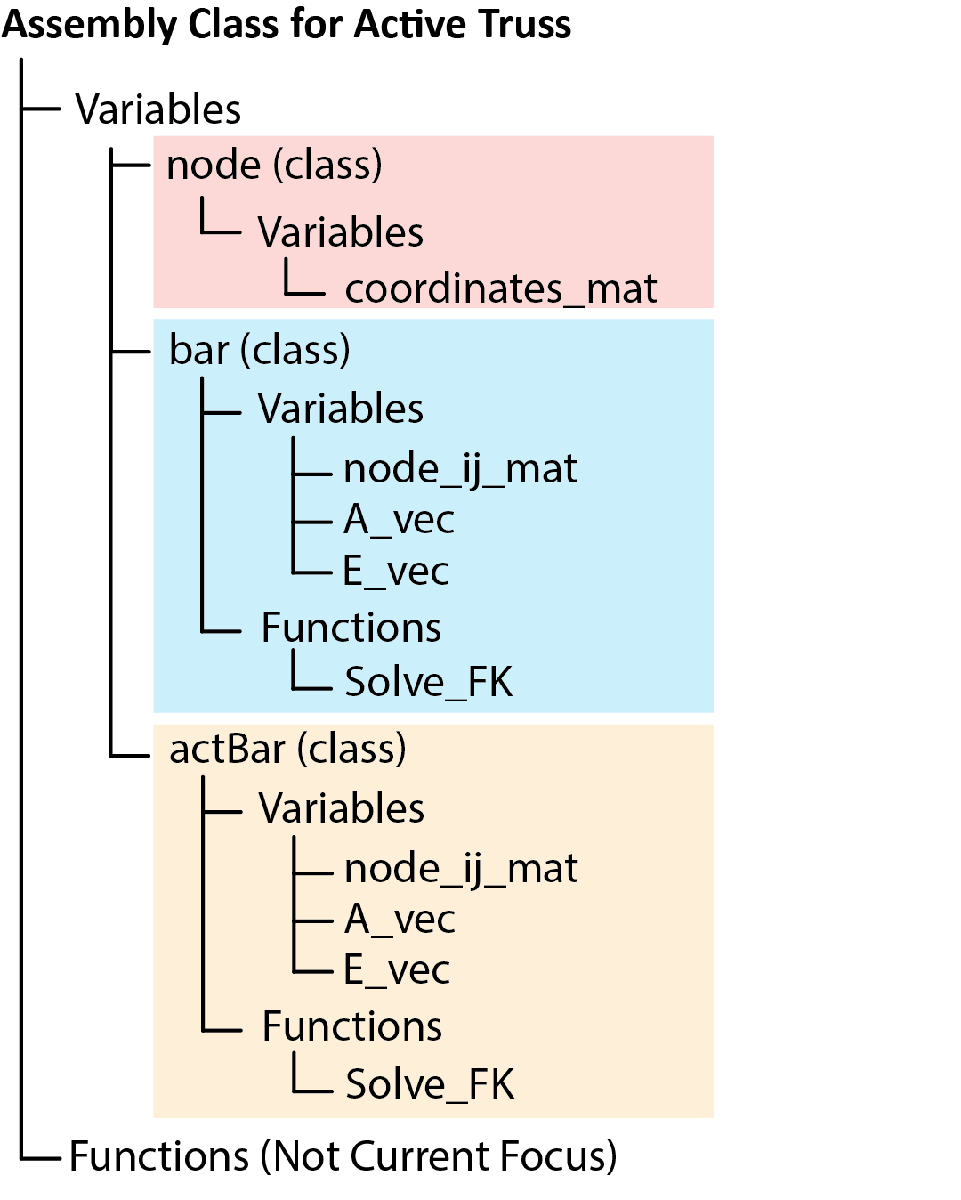

In many simulation platforms, a deformable body (say the active truss) is represented as a clollection of nodes and elements. Using the class in the OOP, we are able to better represent this physical system in the coding environment as shown in the above figure. Here, we create an assembly object based on the assembly class. The assembly will be a collection of the node, the common bar elements, and the active bar elements. This assembly class is defined in the "@Assembly_Truss" folder in the same location of this live script file. Within the properties of the assembly class, we have three primary variables - "node", "bar", and "actBar". We will need to create three objects and assign them to the variables.  

We use the stock vectorized bar element to represent the normal bar and use the stock central-difference based element to represents the active bars (we will learn them soon). These classes can be found in the "SourceCode" folder in side the code package (@Elements_Nodes, @Vec_Elements_Bars, and @CD_Elements_Bars). When defining the item in MATLAB the following code can be used. 

% Create the truss Assembly
assembly=Assembly_Truss;

% Define the node object
node=Elements_Nodes;

% Create the bar object
bar=Vec_Elements_Bars;
actBar=CD_Elements_Bars;

% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.actBar=actBar;

After seting up the objects, we will define the nodal coordinates. Here, a total of 9 node is needed and they are stored in the matrix "coordinates_mat" in the node object. Here the nodes are located in the XZ plane. This is why the second column (Y-axis) is all zero for the matrix. Please keep in mind that our code package is 3D so we cannot omit the Y axis here. 

% Define the nodal coordinates
% Length of each span
L=1; 

% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0 0 0; 
                      L 0 0;
                      0 0 L;
                      L 0 L;
                      0.5*L 0 0.5*L;
                      0 0 2*L;
                      L 0 2*L;
                      0.5*L 0 1.5*L;
                      0.5*L 0 2.5*L;
                      ];

Now, to check if we entered the correct nodal coordinates or not, we can use the plotting function, which is another class we coded. Again, "plots" is an object created out of the class "Plot_Truss" (the folder with the name "@Plot_Truss"). Here, we set the assembly variable in the object to be the "assembly" object we just created. 

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;

Before plotting, we set a couple variable for the plotting function. This include the range we want to plot and the angles we hope to look into the object. Here, 0 for the viewAngle1 and viewAngle2 will give us the XZ plane. We next plot the place of this node. 

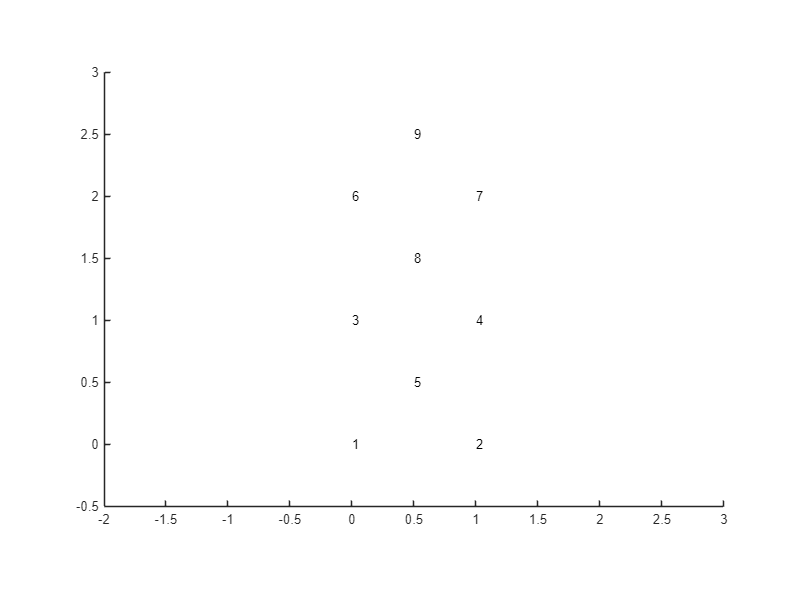

% We will plot for the truss assembly
plots.displayRange=[-2;3;-1;1;-0.5;3]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

Looking good! Now that have the nodes defined, we can further define the two type of bar (truss) elements. Here we need to add rows to the matrix "node_ij_mat" in the bar object. Each row of the matrix gives the two node of one bar. For instance, the first row of the "node_ij_mat" matrix is used to define the first bar element, and this element connects node 1 and node 2. 

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,2;
                 2,5;
                 1,5;
                 3,4;
                 3,5;
                 4,5;
                 3,8;
                 4,8;
                 6,8;
                 7,8;
                 6,7;
                 6,9;
                 7,9;]; 

% Next we design the active truss
actBar.node_ij_mat=[1 3;
                    2 4;
                    3 6;
                    4 7;];

After setting how how bars are connected, we will continue to define the properties of the bar (truss) element - the cross section areas of each truss and the Young's modulus of each truss. This is done with the following code.

% Property of normal truss
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% Property of active truss
activeBarE=2*10^6;

% Define the normal bars
bar.A_vec=barA*ones(13,1);
bar.E_vec=barE*ones(13,1);

% Define the active bars
actBar.A_vec=barA*ones(4,1);
actBar.E_vec=activeBarE*ones(4,1);

Now that we have defined all the structure, we can initialize the full assembly and plot the bar (truss) we just defined. In addition to plotting the shape of the truss, we also have the bar number of each truss shown in the figure. 

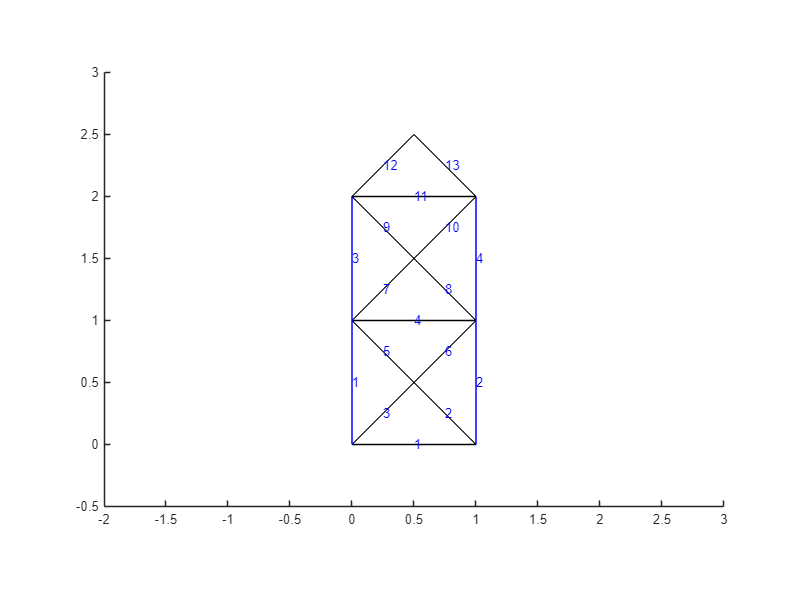

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Plot the bars
plots.Plot_Shape_Bar_Number()

#### **2.4 Teaser: See the Simulated Motion!**

We do not hope to go into the details about setting up the nonlinear solver and solving the deployment in this section. But please let me give you a teaser regarding what we will be able to do with the assembly we created previously! Run the following code, and you will have a active truss that can curl! 

% Define the extension and contraction
deltaL=0.1;
% Set up the self actuation solver
nr=Solver_NR_TrussAction;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,1,1,1;
         3,0,1,0;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;];

% Set up the actuation
nr.targetL0=actBar.L0_vec;

% Find the extention/contraction
nr.targetL0([1,3])=nr.targetL0([1,3])-deltaL;
nr.targetL0([2,4])=nr.targetL0([2,4])+deltaL;

% Set up the total loading step
nr.increStep=10;
% Set up the maximum iteration
nr.iterMax=30;

% Solve for the deformation history
Uhis=nr.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 2.828851e+00 
	Iteration = 2, R = 6.323876e+02 
	Iteration = 3, R = 7.512653e-01 
	Iteration = 4, R = 5.243297e-04 
	Iteration = 5, R = 1.143056e-07 
Icrement = 2
	Iteration = 1, R = 2.830550e+00 
	Iteration = 2, R = 6.269693e+02 
	Iteration = 3, R = 7.393437e-01 
	Iteration = 4, R = 1.522317e-02 
	Iteration = 5, R = 2.815481e-06 
Icrement = 3
	Iteration = 1, R = 2.833949e+00 
	Iteration = 2, R = 6.532256e+02 
	Iteration = 3, R = 8.026728e-01 
	Iteration = 4, R = 1.492934e-01 
	Iteration = 5, R = 3.705509e-05 
	Iteration = 6, R = 1.591289e-09 
Icrement = 4
	Iteration = 1, R = 2.839049e+00 
	Iteration = 2, R = 5.969577e+02 
	Iteration = 3, R = 6.739680e-01 
	Iteration = 4, R = 3.668314e-01 
	Iteration = 5, R = 5.537783e-05 
	Iteration = 6, R = 9.929425e-09 
Icrement = 5
	Iteration = 1, R = 2.845850e+00 
	Iteration = 2, R = 6.660553e+02 
	Iteration = 3, R = 8.357740e-01 
	Iteration = 4, R = 4.832988e-01 
	Iteration = 5, R = 1.3

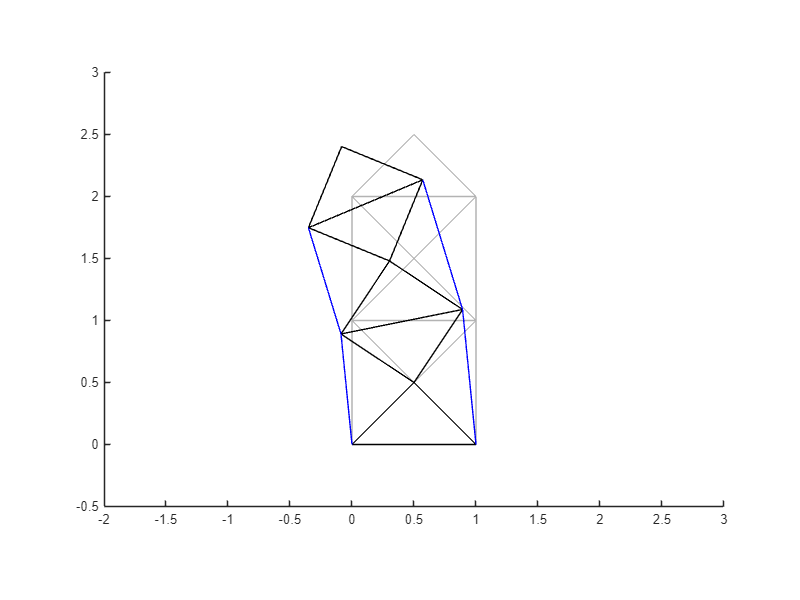

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

Play with the controller to see how the structure can curl in different directions when we specify the bars to deform for different amount. 

#### **2.5 Changing the code without going deep into the package!**

Please open the other live script for this part. What we hope to show you is why OOP is helpful for creating simulation packages. Basically, we the OOP, we do not need to go deep into the code when changing the structure - making it much easier for others to reuse our structure. Let's see if we can create a simulation for the following structure. 

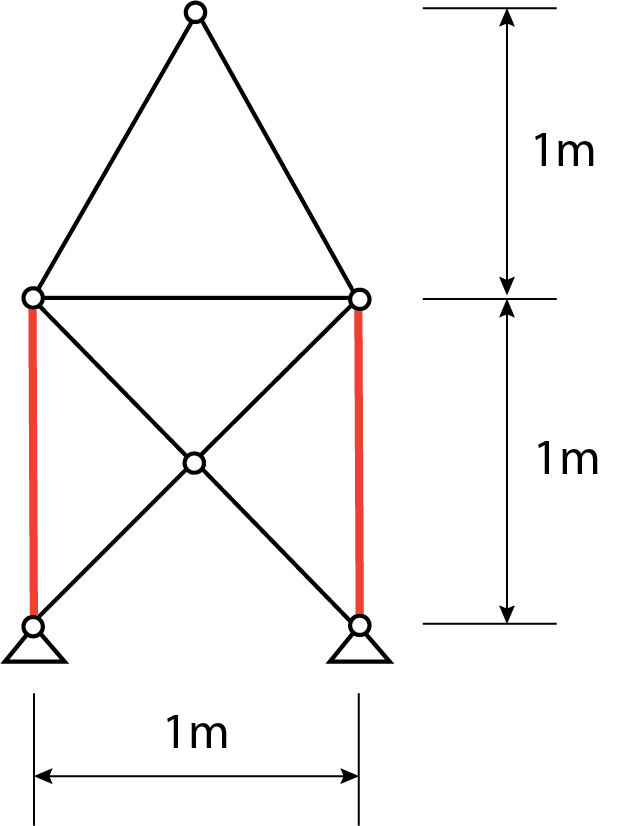

#### **2.6 Reference and Related Class**

Most of the coding class offered in College of Engineering probably already have object oriented programing included. However, for coding, we need to get our hand dirty with the code to actually appreciate the knowledge we learned. So a subtantial amount of coding is usually necessary to really master this.   

See also the introduction of OOP in Wiki:

[https://en.wikipedia.org/wiki/Object-oriented_programming](https://en.wikipedia.org/wiki/Object-oriented_programming)

Also see the documentation for MATLAB OOP:

[https://www.mathworks.com/help/matlab/matlab_oop/why-use-object-oriented-design.html](https://www.mathworks.com/help/matlab/matlab_oop/why-use-object-oriented-design.html)

If you read Chinese check this out:

[https://www.amazon.com/%E5%A4%A7%E8%AF%9D%E8%AE%BE%E8%AE%A1%E6%A8%A1%E5%BC%8F-%E7%A8%8B%E6%9D%B0/dp/B0011FHN5S](https://www.amazon.com/%E5%A4%A7%E8%AF%9D%E8%AE%BE%E8%AE%A1%E6%A8%A1%E5%BC%8F-%E7%A8%8B%E6%9D%B0/dp/B0011FHN5S)

程杰《大话设计模式》我小学初中入门编程时候看的书，非常推荐。